# MTH 4800 Numerical Analysis I Programming Assignment 11

## Jarred Maestas

    1. Using the MATLAB instruction cond, find the condition numbers of Hilbert matrices for $n = 4, 5, ..., 12$. Plot these condition numbers as a function of n using semilogy. What are your observations? How might these matrices be problematic?

n_values = 4:12;
cond_numbers = zeros(size(n_values));

for i = 1:length(n_values)
    n = n_values(i);
    H = hilb(n);  % Generate Hilbert matrix of size n x n
    cond_numbers(i) = cond(H);
    fprintf('n = %2d: cond(H) = %e\n', n, cond_numbers(i));
end

n =  4: cond(H) = 1.551374e+04
n =  5: cond(H) = 4.766073e+05
n =  6: cond(H) = 1.495106e+07
n =  7: cond(H) = 4.753674e+08
n =  8: cond(H) = 1.525758e+10
n =  9: cond(H) = 4.931534e+11
n = 10: cond(H) = 1.602503e+13
n = 11: cond(H) = 5.220207e+14
n = 12: cond(H) = 1.621164e+16


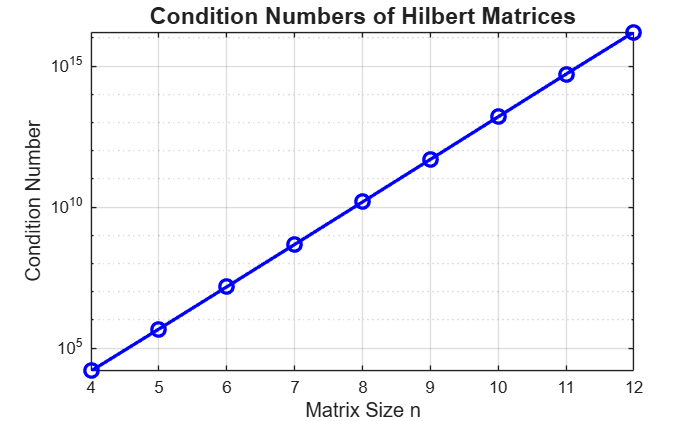


% Plot condition numbers using semilogy
figure('Name', 'Hilbert Matrix Condition Numbers');
semilogy(n_values, cond_numbers, 'b-o', 'LineWidth', 2, 'MarkerSize', 8);
grid on;
xlabel('Matrix Size n', 'FontSize', 12);
ylabel('Condition Number', 'FontSize', 12);
title('Condition Numbers of Hilbert Matrices', 'FontSize', 14);

        - The condition numbers grow exponentially with matrix size such that for $n=12$, $cond(H) \approx 1.621164 \times 10^{16}$, which indicates extreme ill-conditioning. Hilbert matracies are problematic because they become increasingly ill-conditioned as size increases and small pertubations in data lead to larger errors in solutions. This arises more in least squares polynomial fitting, like normal equations, and roun-off erros are aplified significantly

    2. Let us synthesize data in the following way. We start with the cubic polynomial


$$q(t)=11+\frac{55}{3}t-\frac{17}{2}t^2+\frac{7}{6}t^3$$


    Thus, $n = 4$. This is sampled at $33$ equidistant points between $0.9$ and $4.1$. Then we add to these data values $30%$ noise using the random number generator randn in MATLAB, to obtain “the data” which the approximations you will construct “see”. From here on, no knowledge of $q(t)$, its properties, or its values anywhere is assumed: we pretend we don’t know where the data came from!

Your programming task is to pass through these data three approximations:

(a) An interpolating polynomial of degree $32$. This can be done using the MATLAB function $polyfit$, or any of your previous polynomial interpolant codes (NDD).

(b) An interpolating cubic $spline$ using the MATLAB function spline, or your cubic spline code from earlier in the semester.

(c) A cubic polynomial which best fits the data in the $\ell _2$ sense, obtained by our function $lsfit$.

function g = cubic_spline(x, f, bc, xt)
% cubic_spline - Compute cubic spline interpolation
%
% Inputs:
% x  - vector of x-coordinates (knot points)
% f  - vector of function values at x
% bc - boundary condition vector [val1, val2, type] where:
%      type = 1: clamped (val1, val2 are derivative values at endpoints)
%      type = 2: natural (val1, val2 are second derivative values at endpoints)
%      type = NaN: default natural spline (second derivatives = 0)
% xt - evaluation points
%
% Output:
% g  - interpolated values at xt points

    % Input validation
    if length(x) ~= length(f)
        error('x and f must have the same length');
    end
    
    n = length(x) - 1;  % Number of spline segments
    
    % Initialize coefficient matrix A and right-hand side vector B
    A = zeros(4*n, 4*n);
    B = zeros(4*n, 1);
    
    % Pre-compute interval widths for efficiency
    h = diff(x);
    
    % Build the linear system for each spline segment
    for i = 1:n
        % Constraint 1: S_i(x_i) = f_i (function value at left endpoint)
        A(4*i-3, 4*i-3:4*i) = [1, 0, 0, 0];
        B(4*i-3) = f(i);
        
        % Constraint 2: S_i(x_{i+1}) = f_{i+1} (function value at right endpoint)
        A(4*i-2, 4*i-3:4*i) = [1, h(i), h(i)^2, h(i)^3];
        B(4*i-2) = f(i+1);
        
        if i < n  % Interior segments - apply continuity constraints
            % Constraint 3: First derivative continuity S'_i(x_{i+1}) = S'_{i+1}(x_{i+1})
            A(4*i-1, 4*i-3:4*i+4) = [0, 1, 2*h(i), 3*h(i)^2, 0, -1, 0, 0];
            B(4*i-1) = 0;
            
            % Constraint 4: Second derivative continuity S''_i(x_{i+1}) = S''_{i+1}(x_{i+1})
            A(4*i, 4*i-3:4*i+4) = [0, 0, 2, 6*h(i), 0, 0, -2, 0];
            B(4*i) = 0;
        end
    end
    
    % Apply boundary conditions for last segment
    if length(bc) >= 3 && ~isnan(bc(3))
        if bc(3) == 1  % Clamped boundary conditions (specified first derivatives)
            % Left boundary: S'_1(x_1) = bc(1)
            A(4*n-1, 1:4) = [0, 1, 0, 0];
            B(4*n-1) = bc(1);
            
            % Right boundary: S'_n(x_{n+1}) = bc(2)
            A(4*n, 4*n-3:4*n) = [0, 1, 2*h(n), 3*h(n)^2];
            B(4*n) = bc(2);
            
        elseif bc(3) == 2  % Natural boundary conditions (specified second derivatives)
            % Left boundary: S''_1(x_1) = bc(1)
            A(4*n-1, 1:4) = [0, 0, 2, 0];
            B(4*n-1) = bc(1);
            
            % Right boundary: S''_n(x_{n+1}) = bc(2)
            A(4*n, 4*n-3:4*n) = [0, 0, 2, 6*h(n)];
            B(4*n) = bc(2);
        end
    else
        % Default: Natural spline (zero second derivatives at endpoints)
        A(4*n-1, 1:4) = [0, 0, 2, 0];
        A(4*n, 4*n-3:4*n) = [0, 0, 2, 6*h(n)];
        B(4*n-1) = 0;
        B(4*n) = 0;
    end
    
    % Solve the linear system for spline coefficients
    C = A \ B;
    
    % Evaluate the spline at query points
    m = length(xt);
    g = zeros(size(xt));
    
    for i = 1:m
        % Find which segment contains the evaluation point
        for j = 1:n
            if j == n  % Last segment - include right endpoint
                if xt(i) >= x(j) && xt(i) <= x(j+1)
                    % Calculate offset from left endpoint of segment
                    xh = xt(i) - x(j);
                    
                    % Evaluate cubic polynomial: a + b*xh + c*xh^2 + d*xh^3
                    coeff_idx = 4*j - 3;
                    g(i) = C(coeff_idx) + C(coeff_idx+1)*xh + C(coeff_idx+2)*xh^2 + C(coeff_idx+3)*xh^3;
                    break;
                end
            else  % Interior segments - exclude right endpoint to avoid overlap
                if xt(i) >= x(j) && xt(i) < x(j+1)
                    % Calculate offset from left endpoint of segment
                    xh = xt(i) - x(j);
                    
                    % Evaluate cubic polynomial: a + b*xh + c*xh^2 + d*xh^3
                    coeff_idx = 4*j - 3;
                    g(i) = C(coeff_idx) + C(coeff_idx+1)*xh + C(coeff_idx+2)*xh^2 + C(coeff_idx+3)*xh^3;
                    break;
                end
            end
        end
    end
end

function p = lsfit(x, y, n)
% lsfit - Computes least squares polynomial approximation
%
% Inputs:
%   x - vector of data x-coordinates (m data points)
%   y - vector of data y-coordinates (m data points)  
%   n - degree of polynomial to fit (n < m)
%
% Output:
%   p - coefficient vector for polynomial in descending powers
%       [a_n, a_{n-1}, ..., a_1, a_0] such that
%       P(x) = a_n*x^n + a_{n-1}*x^{n-1} + ... + a_1*x + a_0

% Ensure inputs are column vectors
x = x(:);
y = y(:);
m = length(x);

% Validate inputs
if length(y) ~= m
    error('x and y must have the same length');
end
if n >= m
    error('Polynomial degree n must be less than number of data points m');
end
if n < 0
    error('Polynomial degree must be non-negative');
end

% Construct Vandermonde matrix A
% A(i,j) = x(i)^(n-j+1) for i=1:m, j=1:n+1
A = zeros(m, n+1);
for j = 1:(n+1)
    A(:,j) = x.^(n-j+1);
end

% Return coefficients by using QR decomposition of A directly
[Q, R] = qr(A, 0);
p = (R \ (Q' * y))';

end


% Define the true polynomial (unknown to approximation methods)
q = @(t) -11 + (55/3)*t - (17/2)*t.^2 + (7/6)*t.^3;

% Generate 33 equidistant points between 0.9 and 4.1
t_data = linspace(0.9, 4.1, 33);
rng(69);  % Set random seed for reproducibility
noise = 0.3 * randn(size(t_data));  % 30% noise
y_data = q(t_data) + noise;

% Fine grid for plotting
t_plot = linspace(0.9, 4.1, 200);
q_true = q(t_plot);

fprintf('Synthesized %d data points with 30%% noise\n', length(t_data));

Synthesized 33 data points with 30% noise


fprintf('Data range: [%.1f, %.1f]\n\n', min(t_data), max(t_data));

Data range: [0.9, 4.1]




% (a) Interpolating polynomial of degree 32
p_interp = polyfit(t_data, y_data, 32);

y_interp = polyval(p_interp, t_plot);
error_interp = norm(polyval(p_interp, t_data) - y_data);
fprintf('Polynomial of Degree 32 L2 error at data points: %.6e\n', error_interp);

Polynomial of Degree 32 L2 error at data points: 1.313235e+04



% (b) git Interpolating cubic spline
% Using natural spline boundary conditions (default)
bc = [NaN, NaN, NaN];  % Natural spline (second derivatives = 0 at endpoints)
y_spline = cubic_spline(t_data, y_data, bc, t_plot);
y_spline_data = cubic_spline(t_data, y_data, bc, t_data);
error_spline = norm(y_spline_data - y_data);
fprintf('Cubic Spline L2 error at data points: %.15e\n', error_spline);

Cubic Spline L2 error at data points: 2.220446049250313e-16



% (c) Cubic least squares polynomial
p_lsq = lsfit(t_data, y_data, 3);
y_lsq = polyval(p_lsq, t_plot);
error_lsq = norm(polyval(p_lsq, t_data) - y_data);
fprintf('Cubic Least Squares Polynomia L2 error at data points: %.6e\n', error_lsq);

Cubic Least Squares Polynomia L2 error at data points: 1.114898e+00


fprintf('Coefficients: [%.6f, %.6f, %.6f, %.6f]\n', p_lsq);

Coefficients: [1.167076, -8.439507, 18.026706, -10.705677]


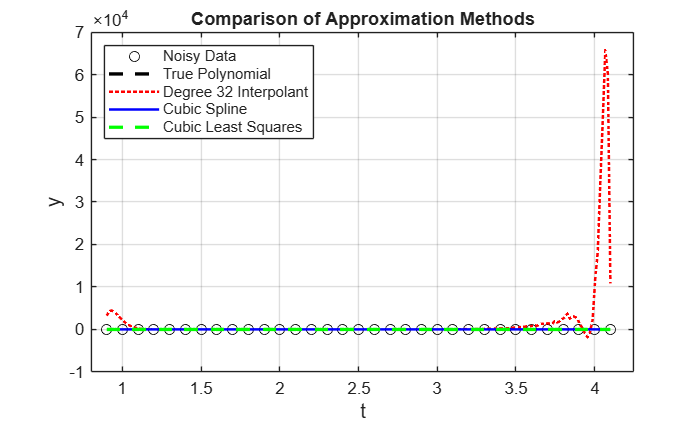


% Plot all three approximations
figure('Name', 'Data Approximation Comparison');
plot(t_data, y_data, 'ko', 'MarkerSize', 6, 'DisplayName', 'Noisy Data');
hold on;
plot(t_plot, q_true, 'k--', 'LineWidth', 2, 'DisplayName', 'True Polynomial');
plot(t_plot, y_interp, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Degree 32 Interpolant');
plot(t_plot, y_spline, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Cubic Spline');
plot(t_plot, y_lsq, 'g--', 'LineWidth', 2, 'DisplayName', 'Cubic Least Squares');
hold off;
grid on;
xlabel('t', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
title('Comparison of Approximation Methods', 'FontSize', 11);
legend('Location', 'northwest');
xlim([0.8, 4.25]);

        - The degree $32$ interpolating polynomial passes through all noisy points exactly but exhibits wild oscillations between data points, with an $\ell _2$ error of $1.31 \times  10^4$ indicating severe numerical instability. This makes it completely unsuitable for approximating noisy data.

        The cubic spline provides smooth $C²$ continuous interpolation with near-zero error at data points ($2.22 \times  10^-{16}$). However, it still follows the noise because it passes through every noisy point exactly.

        The cubic least squares polynomial is the best approximation, effectively filtering out noise while capturing the underlying cubic trend. Its $\ell _2$ error of $1.11$ reflects that it doesn't pass through noisy points exactly, but instead finds the optimal fit. The recovered coefficients $[1.167076, -8.439507, 18.026706, -10.705677]$ closely match the true values $[1.167, -8.500, 18.333, -11.000]$, with differences due to the $30%$ noise. This demonstrates that for noisy data, least squares fitting is superior to interpolation methods.

    3. Find the least squares polynomials of degrees $1$, $2$, and $3$ for the data in the following table.

    Compute the error in each case. Plot the data along with the polynomials, and evaluate their accuracy

% Given data
x_data = [1.0, 1.1, 1.3, 1.5, 1.9, 2.1];
y_data_3 = [1.84, 1.96, 2.21, 2.45, 2.94, 3.18];

% Compute least squares polynomials of degrees 1, 2, and 3
degrees = [1, 2, 3];
errors = zeros(1, 3);
results = containers.Map('KeyType', 'double', 'ValueType', 'any');

for idx = 1:length(degrees)
    deg = degrees(idx);
    p = lsfit(x_data, y_data_3, deg);
    y_approx = polyval(p, x_data);
    errors(idx) = norm(y_data_3 - y_approx);
    results(deg) = struct('coeffs', p, 'y_approx', y_approx);
    
    fprintf('Degree %d Polynomial:\n', deg);
    fprintf('  Coefficients: ');
    fprintf('%.6f ', p);
    fprintf('\n');
    fprintf('  L2 Error: %.6e\n', errors(idx));
    fprintf('  Approximated values: ');
    fprintf('%.4f ', y_approx);
    fprintf('\n\n');
end

Degree 1 Polynomial:


  Coefficients: 

1.219621 0.620895 

  L2 Error: 5.214834e-03


  Approximated values: 

1.8405 1.9625 2.2064 2.4503 2.9382 3.1821 

Degree 2 Polynomial:


  Coefficients: 

-0.010853 1.253293 0.596581 

  L2 Error: 4.244390e-03


  Approximated values: 

1.8390 1.9621 2.2075 2.4521 2.9387 3.1806 

Degree 3 Polynomial:


  Coefficients: 

-0.010047 0.035333 1.185010 0.629019 

  L2 Error: 4.172207e-03


  Approximated values: 

1.8393 1.9619 2.2072 2.4521 2.9392 3.1803 

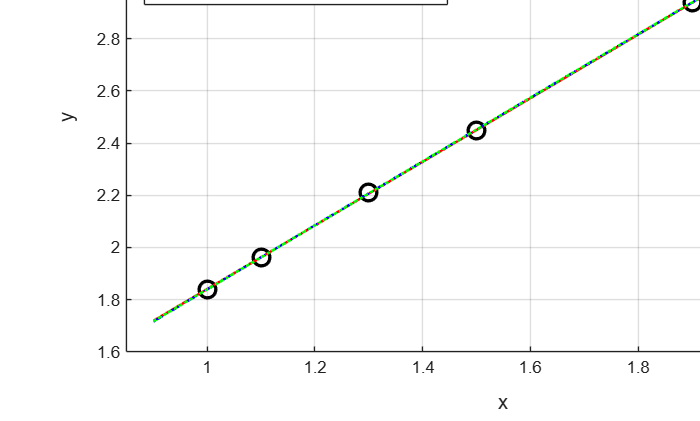


% Plot data and all three polynomial fits
figure('Name', 'Least Squares Polynomial Fits');
plot(x_data, y_data_3, 'ko', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Data');
hold on;
styles = {'-', '--', ':'};
for idx = 1:length(degrees)
    deg = degrees(idx);
    p = results(deg).coeffs;
    y_fit = polyval(p, x_plot);
    plot(x_plot, y_fit, [colors{idx} styles{idx}], 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Degree %d (E=%.2e)', deg, errors(idx)));
end
hold off;
grid on;
xlabel('x', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
title('Polynomial Fits', 'FontSize', 11);
legend('Location', 'northwest');
xlim([0.85, 2.25]);

        - The linear function shows systematic deviations with an $\ell _2$ error of $5.21\times 10⁻³$, underpredicting at the center and overpredicting at the extremes, indicating insufficient model complexity to capture the nonlinear trend.

        The degree 2 polynomial effectively captures the curvature with an $\ell _2$ error of $4.24\times 10⁻³$, representing an 18.6% improvement over the linear fit. This provides an optimal balance between accuracy and simplicity for the dataset.

        The degree 3 polynomial achieves the smallest error at $4.17\times 10⁻³$, but the improvement over degree 2 is only $1.7%$. With 6 data points and 4 parameters, this leaves only 2 degrees of freedom and risks overfitting. The marginal error reduction does not justify the added complexity.